We load all of the data into the workspace. Should move this to another file maybe (whatevers runs when we initialize, maybe the UI file).

air_reference = readtable("Data/air_quality_reference.csv");
sensor_location = readtable("Data/air_quality_sensor_locations.csv");
load("Data/co2_concentration.mat");
load("Data/temperature_humidity.mat");
load("Data/ventilation_system_status.mat");
load("Data/voc_concentration.mat");

We get the variables, clean the data, and graph CO2.

This would probably be better as an standardized method for all of the graphs, a;so needs to be more clear with the data, maybe group it by minutes and clean further. Perhaps use another type of graph (line could be good).I also don't like the colors. 

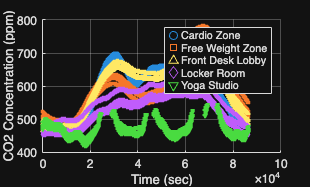

% Converts locations to categorical
groups = categorical(co2_concentration.zone_name);
unique_groups = categories(groups);
shapes_scatter = ['o', 's', '^', 'd', 'v', '+'];
% Makes Graph 
figure;
hold on;

% Loops locations, cleans them, and plots
for i = 1:numel(unique_groups)
    % Find rows that belong to the zone
    zone_mask = (groups == unique_groups{i});
    
    % Gets data for zone
    zone_time = co2_concentration.time_sec(zone_mask);
    zone_co2  = co2_concentration.co2_ppm(zone_mask);
    
    % CLEANING DATA UP

    % Removes missing values
    missing_idx = isnan(zone_co2) | isnan(zone_time);
    zone_time(missing_idx) = [];
    zone_co2(missing_idx)  = [];
    
    % Detect and remove outliers from the data using median
    [zone_co2, outlier_mask] = rmoutliers(zone_co2, 'median');    
    zone_time(outlier_mask) = []; % Remove corresponding times for those outliers   

    % Plots cleaned up data

    zone_co2 = smoothdata(zone_co2, "movmean", SmoothingFactor=0.3);

    scatter(zone_time, ... %y
    zone_co2, ... % x
    5, ... % Size
    shapes_scatter(i), ... % Gives each point a different shape
    'MarkerFaceAlpha', 0.4); % Point Transparency
end

hold off;

% Legend with handwritten names
legend(["Cardio Zone", "Free Weight Zone", "Front Desk Lobby", "Locker Room", "Yoga Studio"])
grid on;
xlabel('Time (sec)');
ylabel('CO2 Concentration (ppm)');

try making a scatterplot with function

disp('Debugging');

Debugging


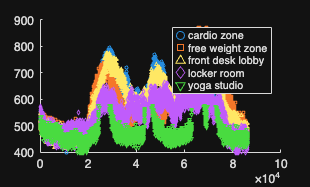

make_scatterplot(co2_concentration.time_sec, co2_concentration.co2_ppm, co2_concentration.zone_name)

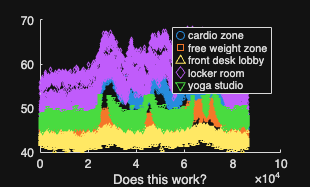

make_scatterplot(temperature_humidity.time_sec, temperature_humidity.relative_humidity_pct, temperature_humidity.zone_name)
xlabel('Does this work?')

Example line plot about temperature. Could add a line displaying the safe measurements

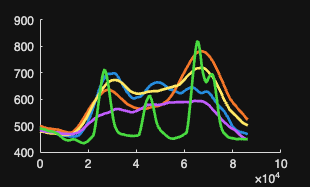


groups = categorical(co2_concentration.zone_name);
unique_groups = categories(groups);

% Makes Graph 
figure;
hold on;


% Loops locations, cleans them, and plots exactly ONE line per area
for i = 1:numel(unique_groups)
    % Find rows that belong to the zone
    zone_mask = (groups == unique_groups{i});

    % Gets data for zone
    zone_time = co2_concentration.time_sec(zone_mask);
    zone_co2  = co2_concentration.co2_ppm(zone_mask);

    % CLEANING DATA UP

    % Removes missing values
    missing_idx = isnan(zone_co2) | isnan(zone_time);
    zone_time(missing_idx) = [];
    zone_co2(missing_idx)  = [];

    %really strong filtering cuts the values in 3 using the mean of
    %multiple values
    [unique_times, ~, idx] = unique(zone_time);
    mean_co2 = accumarray(idx, zone_co2, [], @mean);

    % Smooths the line
    mean_co2 = smoothdata(mean_co2, "movmean", SmoothingFactor=0.3);
       
    % Plots line
    plot(unique_times, mean_co2, 'LineWidth', 2)
end

disp('Example line plots made using the custom function');

Example line plots made using the custom function


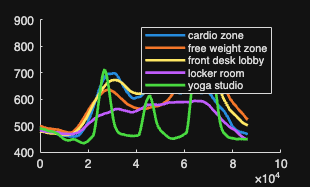

make_lineplot(co2_concentration.time_sec, co2_concentration.co2_ppm, co2_concentration.zone_name)

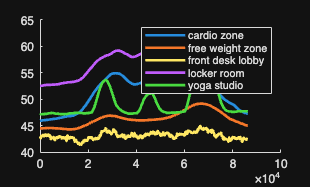

make_lineplot(temperature_humidity.time_sec, temperature_humidity.relative_humidity_pct, temperature_humidity.zone_name)

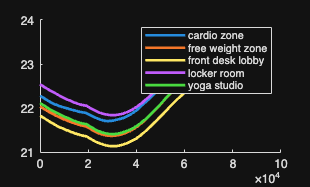


make_lineplot(temperature_humidity.time_sec, temperature_humidity.temperature_C, temperature_humidity.zone_name)

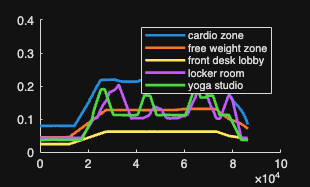

make_lineplot(ventilation_status.time_sec, ventilation_status.supply_airflow_m3_s, ventilation_status.zone_name)


AQI_Calc(temperature_humidity.temperature_C, co2_concentration.co2_ppm, temperature_humidity.relative_humidity_pct, voc_concentration.tvoc_ppb, temperature_humidity.zone_name, "cardio_zone")

ans = 62.6129